addpath('./scripts')

Generate synthetic data according to ICA model:

% ica1 = sim_basic_ICA(100, 16, 16, 20000, 5, 1000);
% X = ica1.genX();

Inspect

% seed = 100;
% K = 16;
% V = K;
% M_Tot = 2;
% N = 200000;
% Acond = 5;
% SNR = 999+1/1;
% 
% % iva1 = sim_basic_IVA(seed,K,V,M_Tot,N,Acond,SNR);
% 
% plot(iva1.Y{1}(end,:)',iva1.Y{2}(end,:)','.r')
% h = histogram2(iva1.Y{1}(end,:)',iva1.Y{2}(end,:)','DisplayStyle','tile','Normalization','pdf');
% vals = h.Values;
% x = h.XBinEdges(1:(end-1));
% y = h.YBinEdges(1:(end-1));
% [X,Y] = meshgrid(x,y);
% contour(X',Y',log10(log10(vals+1)))
% corr(iva1.Y{1}(end,:)',iva1.Y{2}(end,:)')
% 
% histogram(iva1.Y{1}(end,:)')
% 

Association between subspaces should be 0:

% plot(iva1.Y{1}(1,:)',iva1.Y{2}(end,:)','.r')
% h = histogram2(iva1.Y{1}(1,:)',iva1.Y{2}(end,:)','DisplayStyle','tile','Normalization','pdf');
% vals = h.Values;
% x = h.XBinEdges(1:(end-1));
% y = h.YBinEdges(1:(end-1));
% [X,Y] = meshgrid(x,y);
% contour(X',Y',log10(log10(vals+1)))
% corr(iva1.Y{1}(1,:)',iva1.Y{2}(end,:)')

Using gsd class directly:

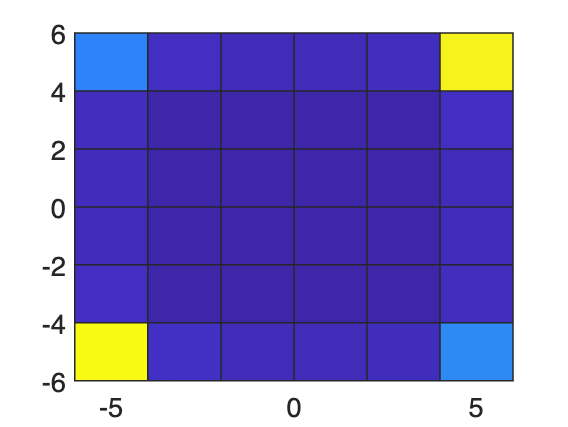

seed = 100;
num_obs = 20000; % 50 500 5000 50000;
total_datasets = 2;
num_subspaces = 16; % 32 64 128

% Subspace Assignment Matrix (SAM)
SAM = num2cell(repmat((1:num_subspaces)', 1, total_datasets));
num_sources = [];
for mm = 1:total_datasets
    num_sources = [num_sources sum([SAM{:,mm}] ~= 0)];
end

% Define parameters for subspace distributions
half_ns = num_subspaces/2;
max_subspace_corr = [linspace(.1,.7,half_ns),linspace(.15,.75,half_ns)]';
subspace_std = 2.^[linspace(2,-3,half_ns),linspace(-3,2,half_ns)]';
nn = 1;
for kk = 1:num_subspaces
    dist_params(kk).name = 'gcp';
    dist_params(kk).mu   = zeros(sum([SAM{kk,:}] ~= 0),1);
    dist_params(kk).CORR = max_subspace_corr(kk);
    if length(dist_params(kk).mu) > 1 && strcmpi(dist_params(kk).name, 'gcp')
        % Define parameters for marginal distributions
        marginal_names = {'laplace', 'logistic', 'normal', 'uniform', 'beta'};%, 'bimodal_gamma'};
        for cc = 1:length(dist_params(kk).mu)
            dist_params(kk).gcp_marginals(cc).name = marginal_names{nn};
            dist_params(kk).gcp_marginals(cc).mu = dist_params(kk).mu(cc);
            switch(lower(dist_params(kk).gcp_marginals(cc).name))
                case 'laplace'
                    dist_params(kk).gcp_marginals(cc).sd = subspace_std(kk); % pi/sqrt(3);
                case 'logistic'
                    dist_params(kk).gcp_marginals(cc).sd = subspace_std(kk);
                case 'normal'
                    dist_params(kk).gcp_marginals(cc).sd = subspace_std(kk);
                case 'uniform'
                    dist_params(kk).gcp_marginals(cc).sd = subspace_std(kk);
                case 'beta'
                    dist_params(kk).gcp_marginals(cc).sd = subspace_std(kk);
                    dist_params(kk).gcp_marginals(cc).a = 0.05;
                    dist_params(kk).gcp_marginals(cc).b = 0.05;
                case 'bimodal_gamma'
                    M = .75 * (subspace_std(kk)); % Gamma Mode
                    VV = (.785*subspace_std(kk))^2; % Total Variance (~2*GammaVariance)
                    dist_params(kk).gcp_marginals(cc).a = (VV + 2*M^2 + 2*M*sqrt(VV + M^2))/VV;
                    dist_params(kk).gcp_marginals(cc).b = M/(dist_params(kk).gcp_marginals(cc).a-1);
%                     (a-1)*b
%                     sqrt(a*(b^2))
%                     a
%                     b
                otherwise
                    error('Invalid distribution name.');
            end
            
            
        end
        if nn < length(marginal_names)
            nn = nn + 1;
        else
            nn = 1;
        end
    end
end
data_dim = num_sources;
Atype   = 'Generated';
Acond   = 3;
A       = {};
SNR     = (999+1)/1; % (signal power + noise power) / noise power 
predictors = cell(1,M_Tot);
regtype = 'LS';

sim1    = gsd(seed, num_obs, total_datasets, num_subspaces, num_sources, ...
    SAM, dist_params, data_dim, Atype, Acond, A, SNR, predictors, regtype);

h = histogram2(sim1.Y{1}(end-1,:)',sim1.Y{2}(end-1,:)','DisplayStyle','tile','Normalization','pdf');

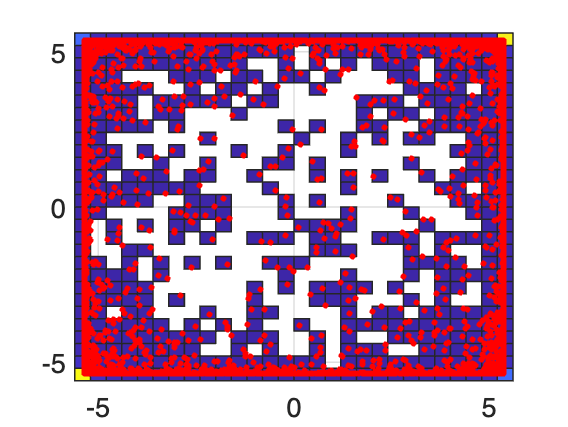

h = histogram2(sim1.Y{1}(end-1,:)',sim1.Y{2}(end-1,:)','BinWidth',h.BinWidth./5,'DisplayStyle','tile','Normalization','pdf');
hold on
plot(sim1.Y{1}(end-1,:)',sim1.Y{2}(end-1,:)','.r')
hold off

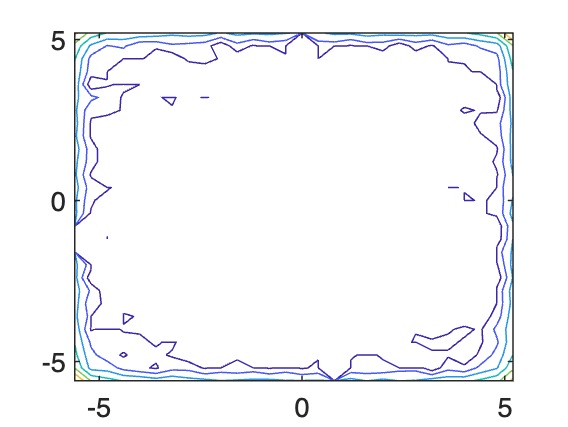


vals = h.Values;
x = h.XBinEdges(1:(end-1));
y = h.YBinEdges(1:(end-1));
[X,Y] = meshgrid(x,y);
contour(X',Y',log10(log10(vals+1)))

corr(sim1.Y{1}(end-1,:)',sim1.Y{2}(end-1,:)')

ans = 0.5010

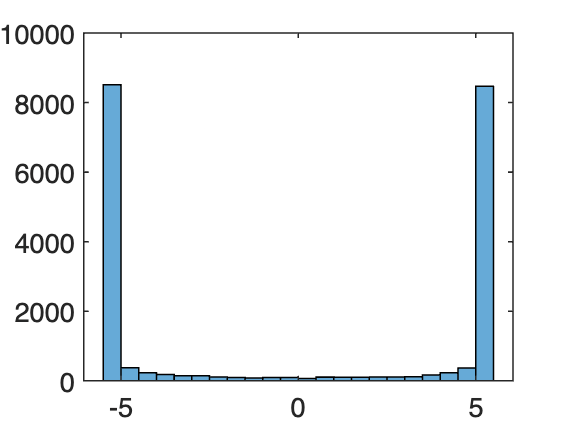


histogram(sim1.Y{1}(end-1,:)')


% Marginal_distribution = laplace, logistic, uniform, bimodal? (group_difference), mismatched (NEW!)

% Num_sources_estiamted = (.5:.25:1.5) * num_sources